Test script for the LacI titration data. 

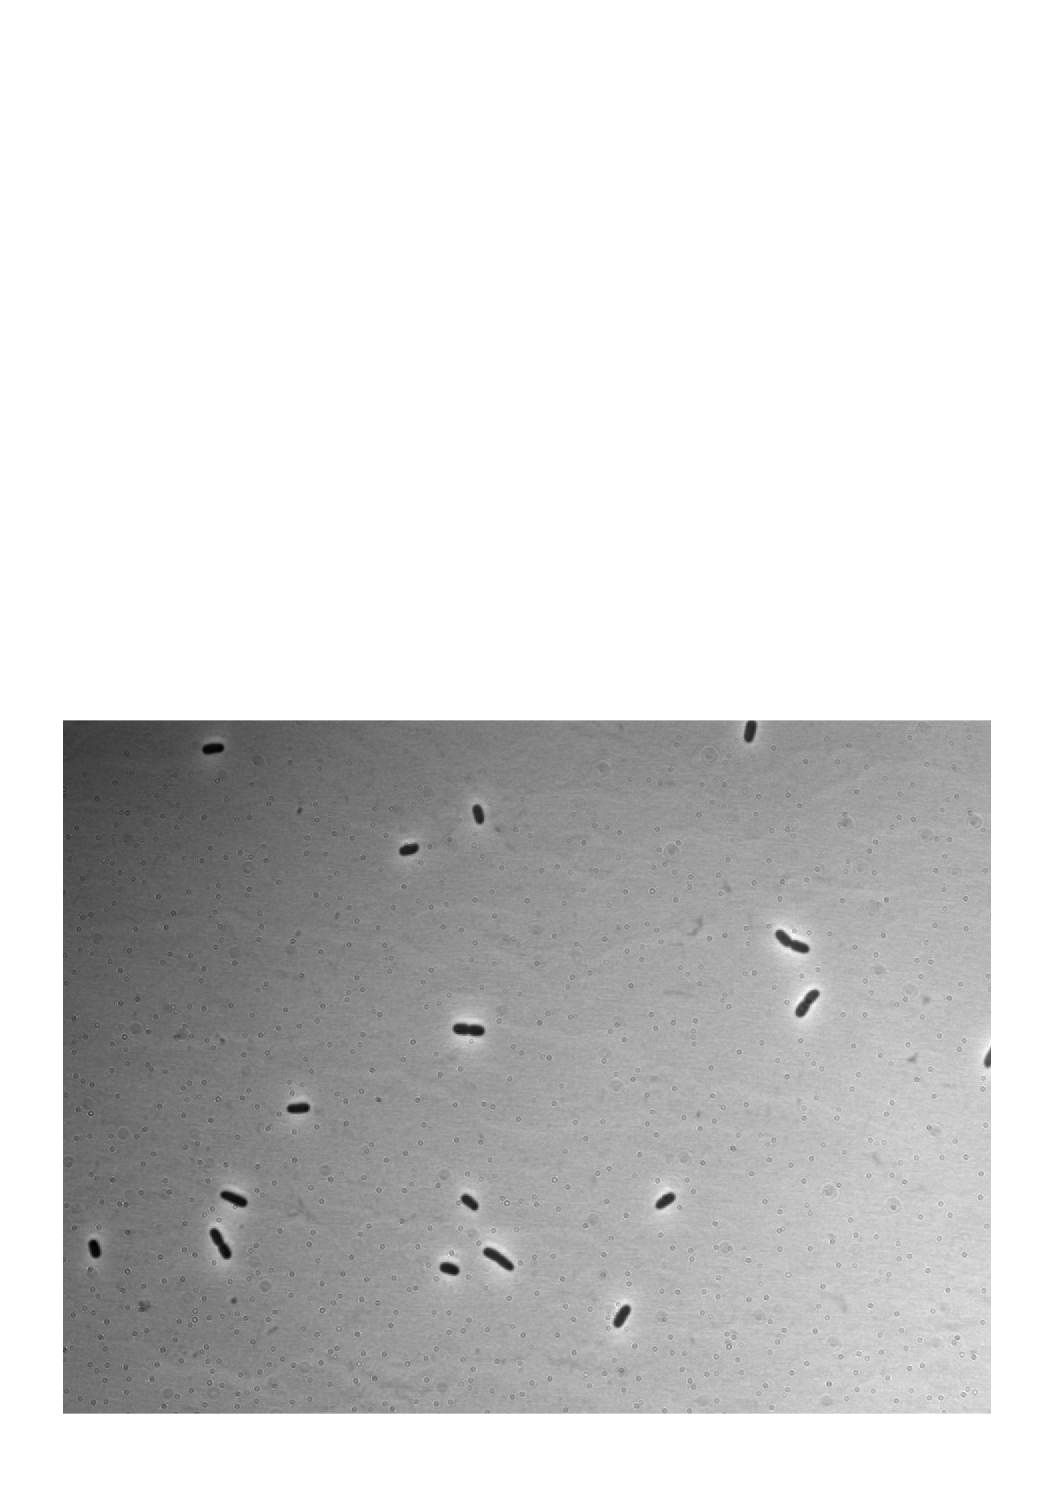

%Define the image directory and load up an example phase image. 
image_dir = 'lacI_titration_data/';
test_im = 'noLac_phase_0000.tif';

%Load up the image and display it. 
phase_im = imread([image_dir test_im]);
imshow(phase_im, [])

There is uneven illumination. This can be corrected by performing a large gaussian blur and subtracting. 

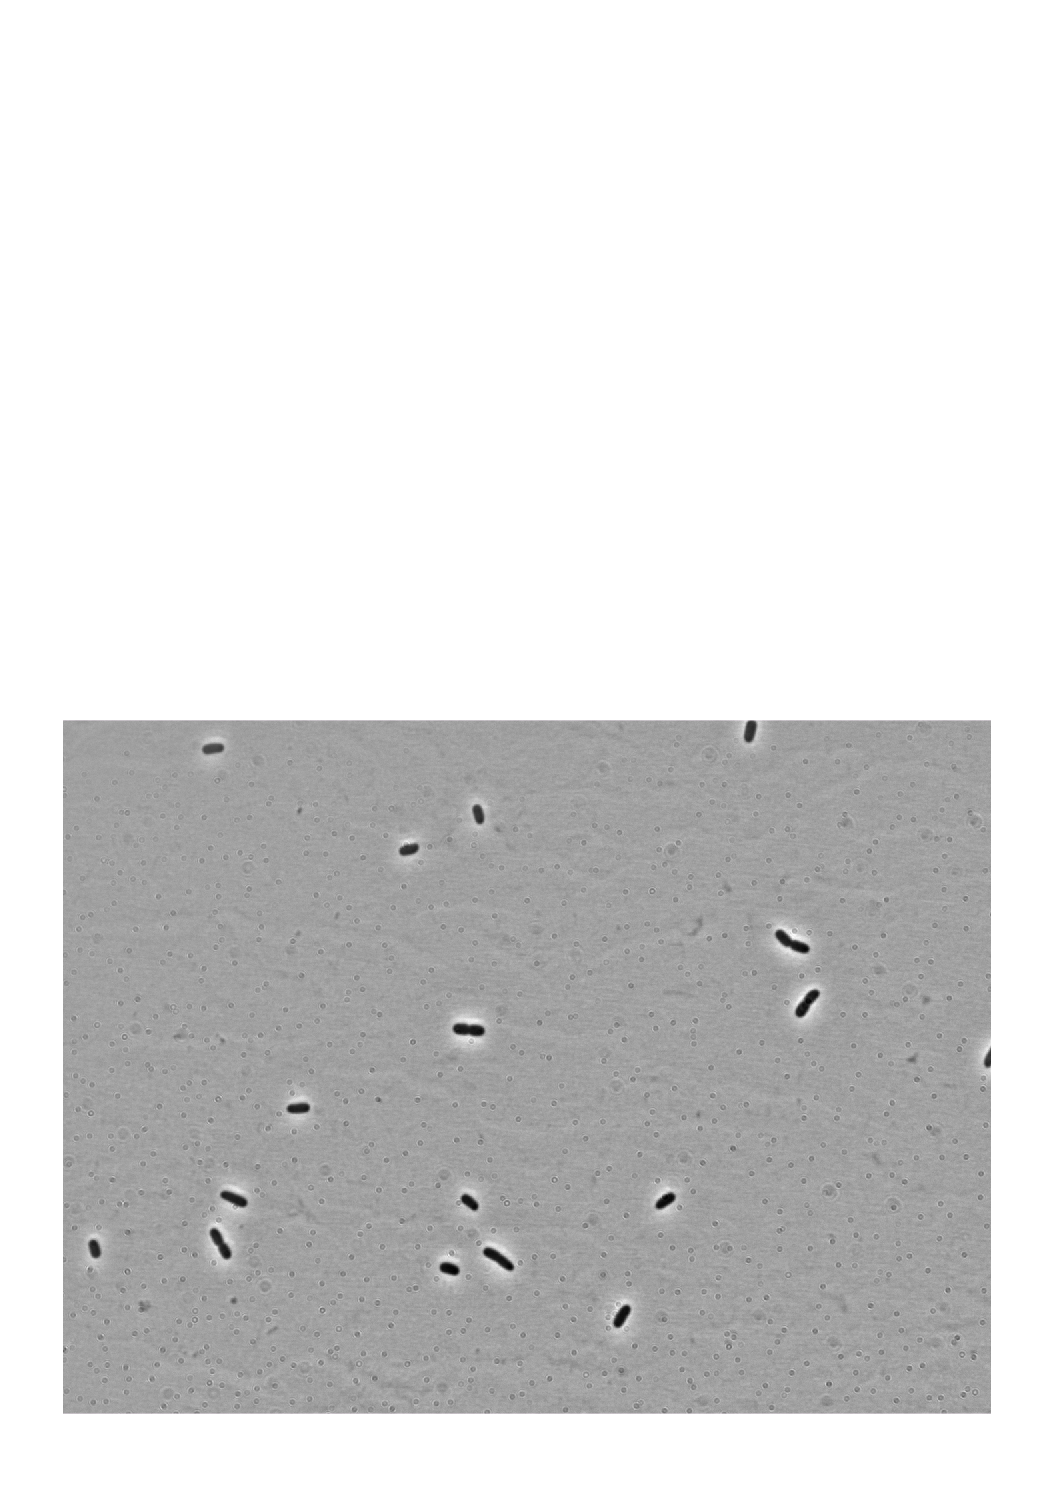

%Convert the image to a float. 
phase_im = mat2gray(phase_im);

%Blur the image using a gaussian filter. 
filt_im = imgaussfilt(phase_im, 20);

%Subtract them. 
im_sub = phase_im - filt_im;

%Show it. 
imshow(im_sub, [])

Now we can look at the histogram of this image to choose a threshold to separate bacteria from background.

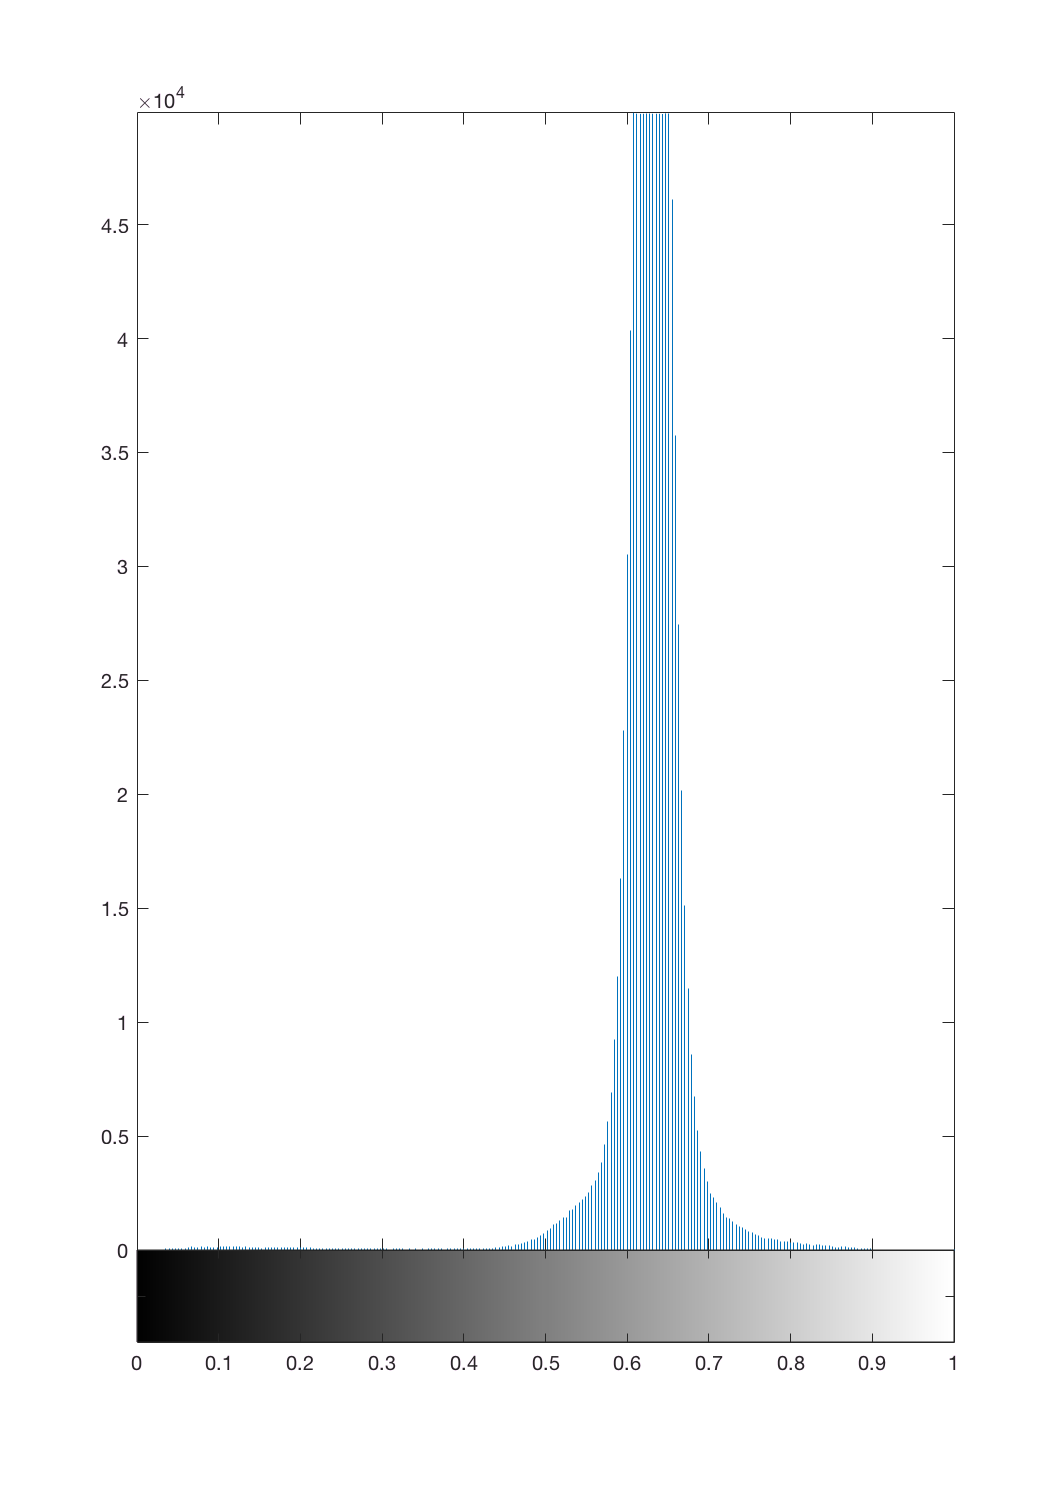

%Set the number of bins
im_sub = mat2gray(im_sub);
bins = 100;
imhist(im_sub)

By eye, a good threshold might be around 0.2.

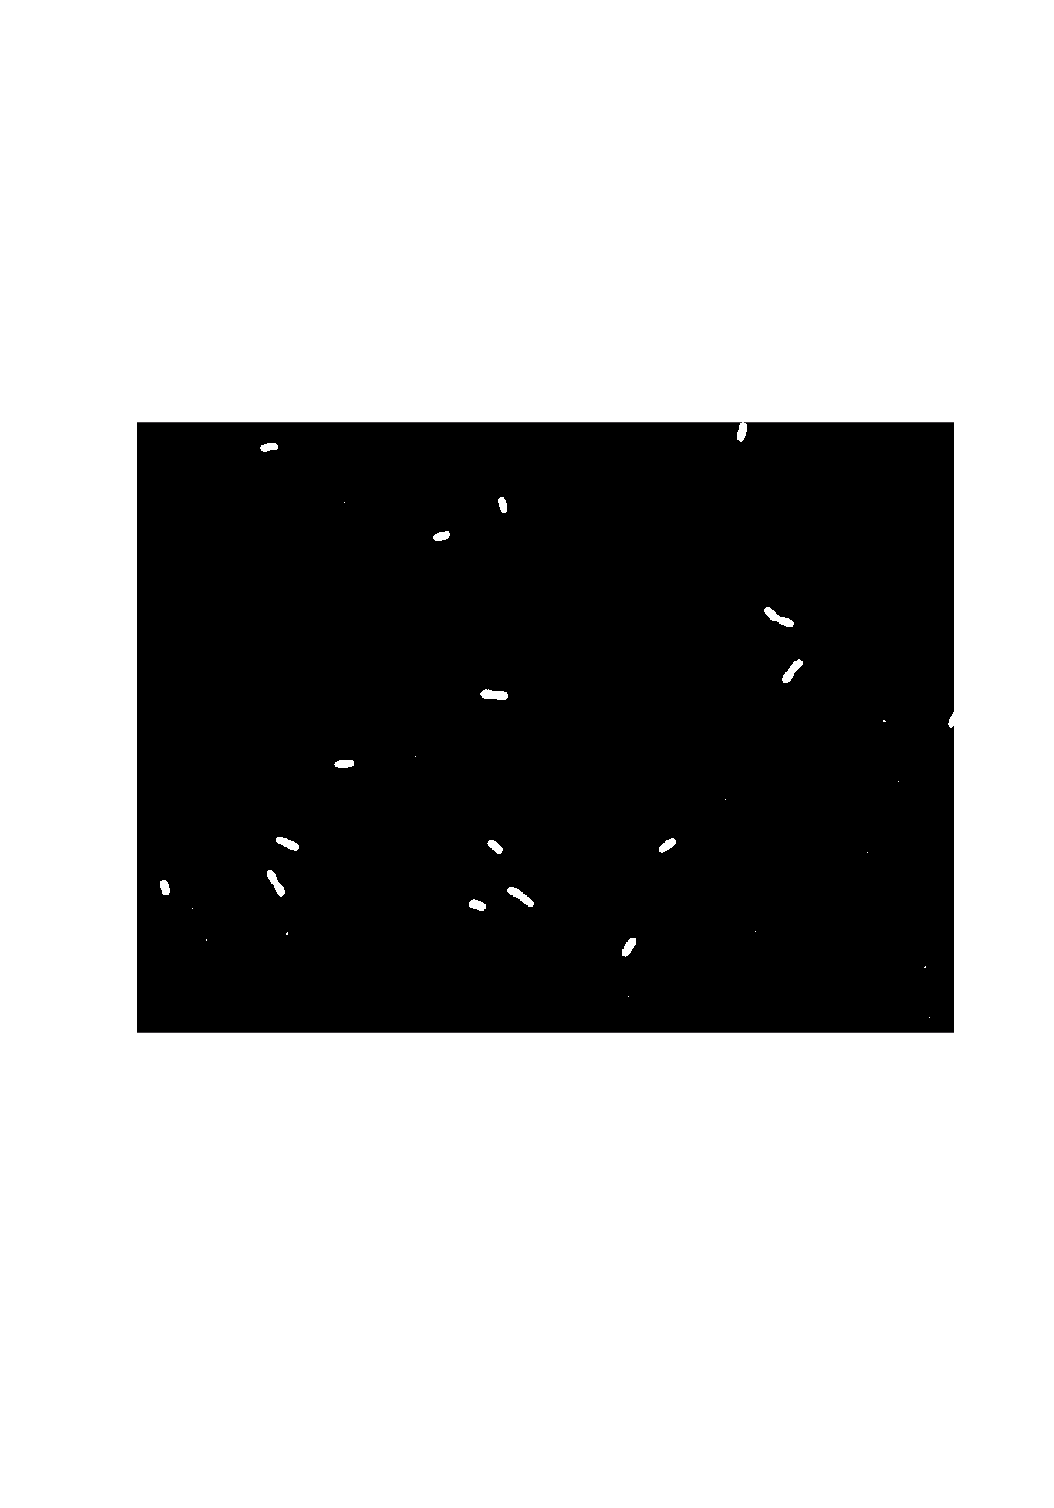

%Apply the threshold to the image. 
thresh = 0.4;
im_thresh = im_sub < thresh;
imshow(im_thresh)

We did a pretty good job, although there is some small shit in the background. Let's try to delete them. 

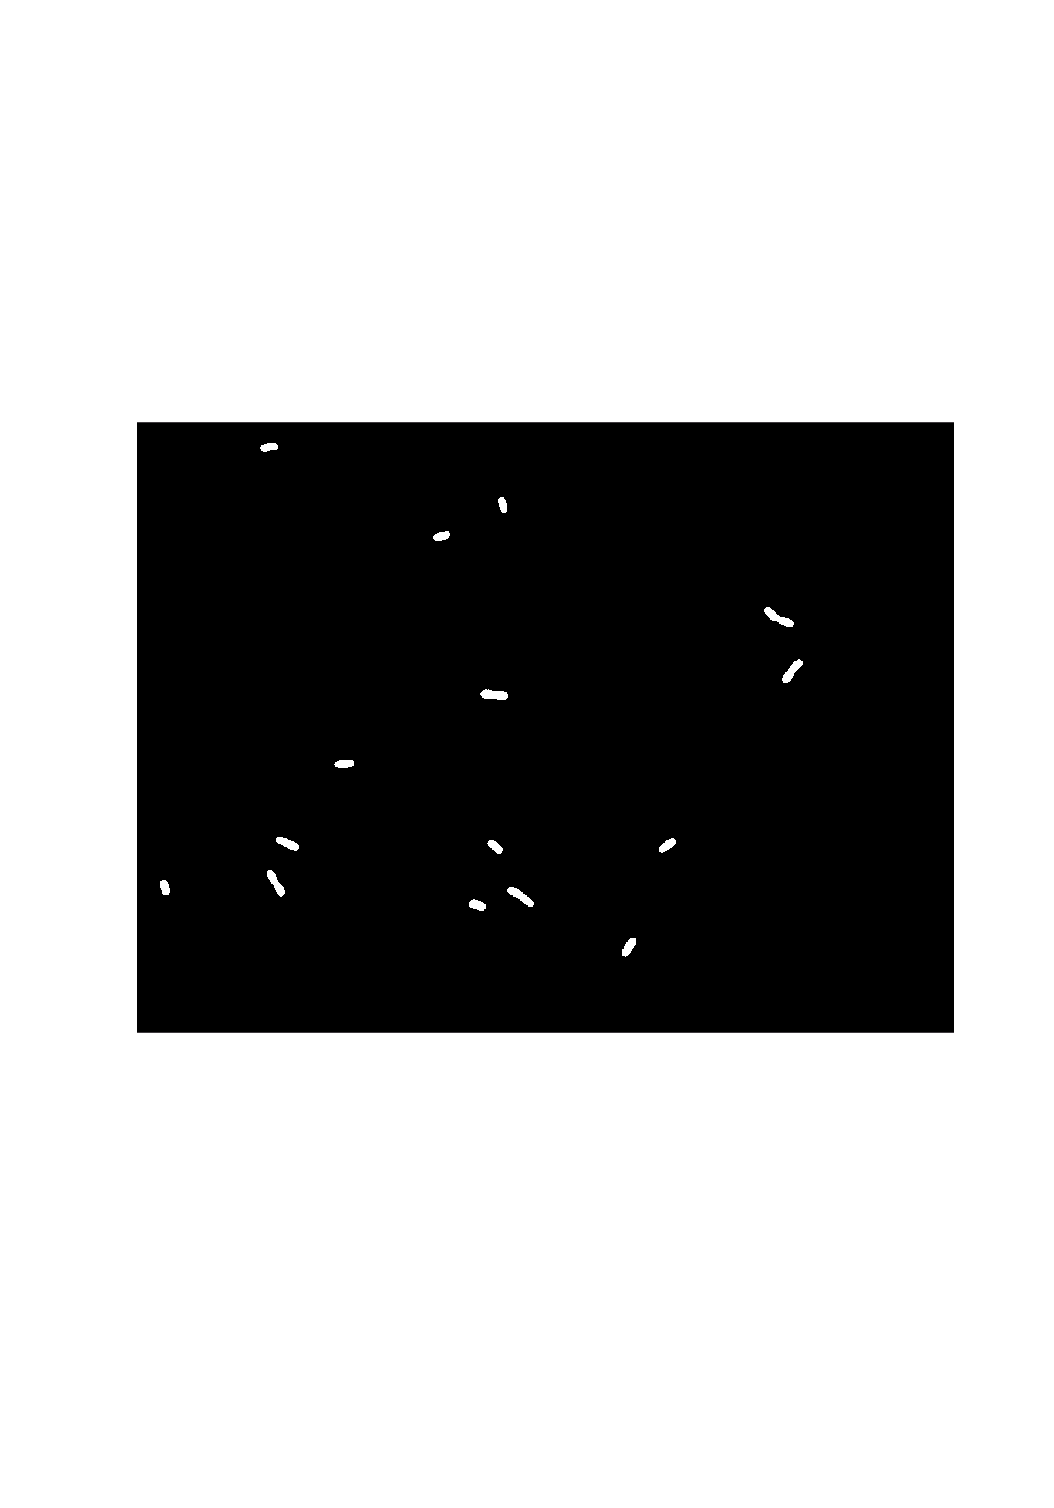

%Remove the small objects
im_cells = bwareaopen(im_thresh, 100);

%Delete cells touching the edge.
im_cells = imclearborder(im_cells);
imshow(im_cells);

 all we have to do is label our cells.

%Label the image and extract the cell areas. 
im_label = bwlabel(im_cells);
props = regionprops(im_label, 'Area');
areas = [props.Area];
%Convert the areas to square microns given the interpixel distance. 
ip_dist = 0.0635; %in µm.
areas = areas * ip_dist^2;

Now let's write a function to do all of this for us.

See addditional file. 

%Define all images of the autofluorescence sample. 
phase_images = dir([image_dir 'noYFP_phase*'])

phase_images = 8x1 struct array with fields:

    name
    folder
    date
    bytes
    isdir
    datenum


FITC_images = dir([image_dir 'noYFP_FITC*'])

FITC_images = 8x1 struct array with fields:

    name
    folder
    date
    bytes
    isdir
    datenum



%Sort by autofluorescence images first. 
auto = [];
for i=1:length(phase_images)
     seg = segmentation([image_dir phase_images(i).name], 0.4);
     int_im = imread([image_dir FITC_images(i).name]);
     props = regionprops(seg, int_im, 'MeanIntensity');
     auto = [auto [props.MeanIntensity]];
end


  

Now that we have all of the mean pixel values, let's compute an average to subtract from the other samples. 

%Compute the mean autofluorescence. 
mean_auto = mean(auto);

For simplicity, we'll write the above stuff as a function. 

%Set up a list of patterns. 
phase_patterns = ['NoLac_phase*', 'WT_phase', 'RBS1_phase', 'RBS446_phase', 'RBS1147_phase', 'RBS1037_phase']

phase_patterns = NoLac_phase*WT_phaseRBS1_phaseRBS446_phaseRBS1147_phaseRBS1037_phase

fl_patterns = ['NoLac_FITC', 'WT_FITC', 'RBS1_FITC', 'RBS446_FITC', 'RBS1147_FITC', 'RBS1037_FITC']

fl_patterns = NoLac_FITCWT_FITCRBS1_FITCRBS446_FITCRBS1147_FITCRBS1037_FITC


%Extract the autofluorescence corrected intensities.
thresh = 0.4

thresh = 0.3500

delta = extract_mean_int(image_dir, 'NoLac_phase*', 'NoLac_FITC*', thresh, mean_auto);
wt = extract_mean_int(image_dir, 'WT_phase*', 'WT_FITC*', thresh, mean_auto);
rbs1 = extract_mean_int(image_dir, 'RBS1_phase*', 'RBS1_FITC*', thresh, mean_auto);
rbs1037 = extract_mean_int(image_dir, 'RBS1037_phase*', 'RBS1037_FITC*', thresh, mean_auto);
rbs1147 = extract_mean_int(image_dir, 'RBS1147_phase*', 'RBS1147_FITC*', thresh, mean_auto);
rbs446 = extract_mean_int(image_dir, 'RBS446_phase*', 'RBS446_FITC*', thresh, mean_auto);


Now let's compute the fold change for each. 

%Compute mean fold change for each sample. 
fc_wt = mean(wt) / mean(delta);
fc_rbs1 = mean(rbs1) / mean(delta);
fc_rbs1037 = mean(rbs1037) / mean(delta);
fc_rbs1147 = mean(rbs1147) / mean(delta);
fc_rbs446 = mean(rbs446) / mean(delta);

%Now compute the standard errors of each. 
err_wt = std(wt) / sqrt(length(wt));
err_delta = std(delta) / sqrt(length(delta));
err_rbs1 = std(rbs1) / sqrt(length(rbs1));
err_rbs1037 = std(rbs1037) / sqrt(length(rbs1037));
err_rbs1147 = std(rbs1147) / sqrt(length(rbs1147));
err_rbs446  = std(rbs446) / sqrt(length(446));

%Now the total error. 
terr_wt = fc_wt * sqrt((err_wt / mean(wt))^2 + (err_delta / mean(delta))^2)

terr_wt = 0.0109

terr_rbs1 = fc_rbs1 * sqrt((err_rbs1 / mean(rbs1))^2 + (err_delta / mean(delta))^2)

terr_rbs1 = 0.0022

terr_rbs1037 = fc_rbs1037 * sqrt((err_rbs1037 / mean(rbs1037))^2 + (err_delta / mean(delta))^2)

terr_rbs1037 = 0.0040

terr_rbs1147 = fc_rbs1147 * sqrt((err_rbs1147 / mean(rbs1147))^2 + (err_delta / mean(delta))^2)

terr_rbs1147 = 0.0072

terr_rbs446 = fc_rbs446 * sqrt((err_rbs446 / mean(rbs446))^2 + (err_delta / mean(delta))^2)

terr_rbs446 = 0.0634

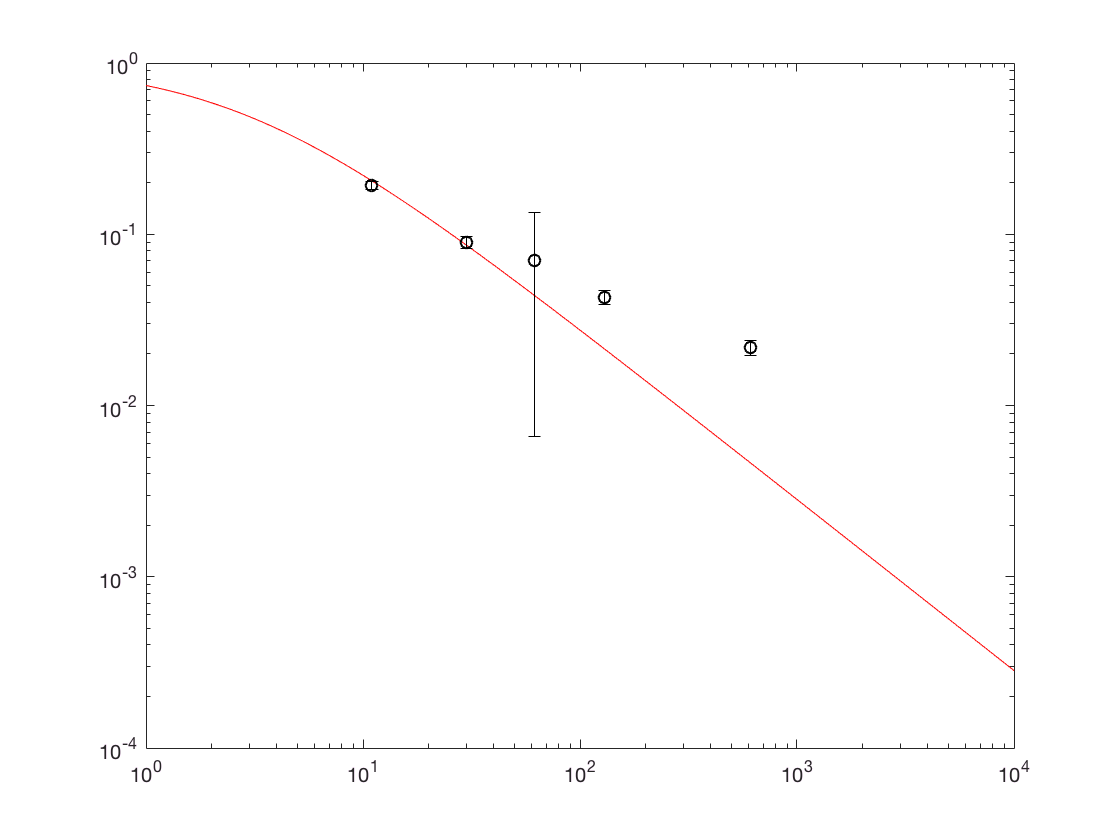



%Compile all the data for easy plotting
fc = [fc_wt, fc_rbs1, fc_rbs1037, fc_rbs1147, fc_rbs446];
fc_err = [terr_wt, terr_rbs1, terr_rbs1037, terr_rbs1147, terr_rbs446];
measured_r = [11, 610, 130, 30, 62];
measured_r_err = [2, 80, 20, 10, 15]; 
R = logspace(0, 4, 1000);
Nns = 4.6E6;
dEr = -14.3;
theo = 1 ./ (1 + (R./Nns) * exp(-dEr));
close('all')
loglog(R, theo, 'r-')
hold on;
loglog(measured_r, fc, 'ko');
%errorbar(fc, measured_r, measured_r_err, 'ko');
errorbar(measured_r, fc, fc_err, 'ko');
hold off;